## 均匀介质聚焦

本code是为了复现Peter Torok的论文**Computational methods in vectorial imaging（**[https://doi.org/10.1080/09500340.2010.525668](https://doi.org/10.1080/09500340.2010.525668)**）**。这篇文章主要讲利用高数值孔径透镜成像的计算问题。

#### 符号运算

syms theta ex ey ez phi
Ei = [ex ey ez].';
R = [cos(phi) sin(phi) 0;
    -sin(phi) cos(phi) 0;
    0 0 1];
L = [cos(theta) 0 -sin(theta);
    0 1 0;
    sin(theta) 0 cos(theta)];
e = simplify(inv(R)*L*R*Ei)

$$e = \left(\begin{array}{c} \mathrm{ex}-\mathrm{ex}\,{\cos\left(\varphi \right)}^{2}-\mathrm{ey}\,\cos\left(\varphi \right)\,\sin\left(\varphi \right)-\mathrm{ez}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+\mathrm{ex}\,{\cos\left(\varphi \right)}^{2}\,\cos\left(\theta \right)+\mathrm{ey}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \mathrm{ey}\,\cos\left(\theta \right)+\mathrm{ey}\,{\cos\left(\varphi \right)}^{2}-\mathrm{ex}\,\cos\left(\varphi \right)\,\sin\left(\varphi \right)-\mathrm{ez}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\mathrm{ey}\,{\cos\left(\varphi \right)}^{2}\,\cos\left(\theta \right)+\mathrm{ex}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \mathrm{ez}\,\cos\left(\theta \right)+\mathrm{ex}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+\mathrm{ey}\,\sin\left(\varphi \right)\,\sin\left(\theta \right) \end{array}\right)$$

#### 均匀介质聚焦

Torok原始论文的公式有符号上的问题，所以不能复现出他给出的结果（不仅仅是琼斯矩阵上定义的符号问题，还包括誊写计算结果的时候出现的笔误），这里完全采用自己对琼斯矩阵的理解写定的公式并加以推导，结果跟论文模拟结果相符合。

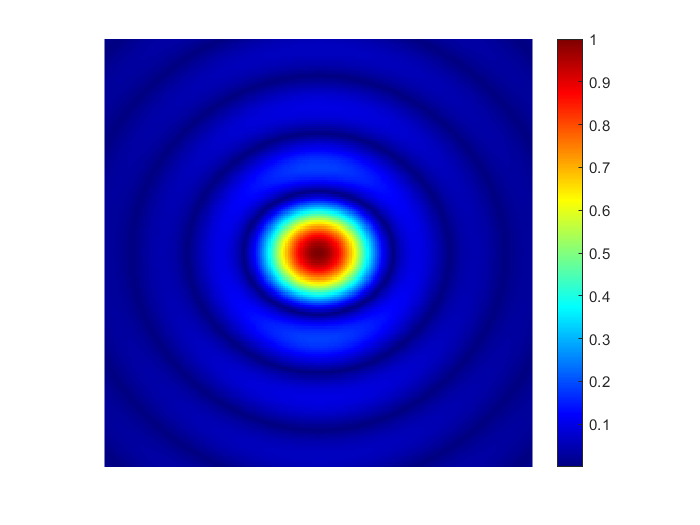

clear
lambda = 670*1e-9;
k = 2*pi/lambda;
x = (-2:0.02:2)*lambda;
y = x;
[x,y] = meshgrid(x,y);
[phi,rho] = cart2pol(x,y);
alp = asin(0.95);
z = 0*1e-6;     % 焦面位置

Exi = 1;
Eyi = 0;
Ezi = 0;

f0 = @(theta) sqrt(cos(theta)).*sin(theta).*(cos(theta) + 1)...
    .*besselj(0,k*rho*sin(theta)).*exp(1i*k*z*cos(theta));
f1 = @(theta) sqrt(cos(theta)).*(sin(theta).^2)...
    .*besselj(1,k*rho*sin(theta)).*exp(1i*k*z*cos(theta));
f2 = @(theta) sqrt(cos(theta)).*sin(theta).*(cos(theta) - 1)...
    .*besselj(2,k*rho*sin(theta)).*exp(1i*k*z*cos(theta));
I0 = integral(f0,0,alp,'ArrayValued',1);
I1 = integral(f1,0,alp,'ArrayValued',1);
I2 = integral(f2,0,alp,'ArrayValued',1);

Ex = Exi.*(I0 - I2.*cos(2*phi)) - Eyi.*I2.*sin(2*phi);
Ey = Eyi.*(I0 + I2.*cos(2*phi)) - Exi.*I2.*sin(2*phi);
Ez = 2*1i*I1.*(Exi.*cos(phi) + Eyi.*sin(phi));

P = max(abs(Ex),[],'all');
Ex = Ex/P;
Ey = Ey/P;
Ez = Ez/P;

figure
imagesc(abs(Ex))
axis off 
axis square
colormap(jet)
colorbar

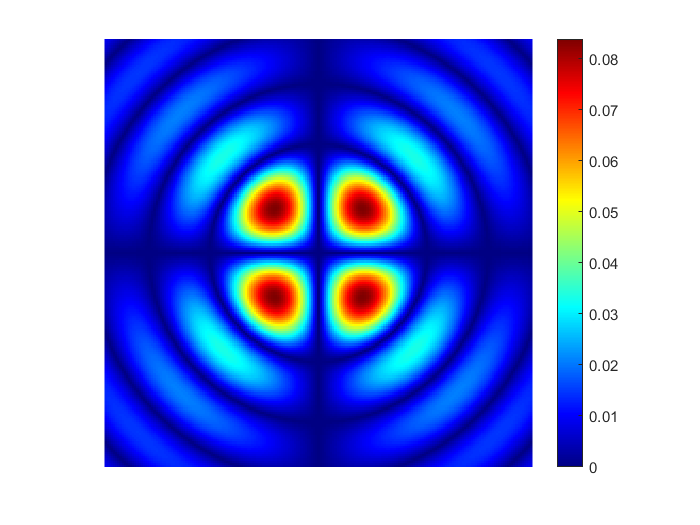

figure
imagesc(abs(Ey))
axis off 
axis square
colormap(jet)
colorbar

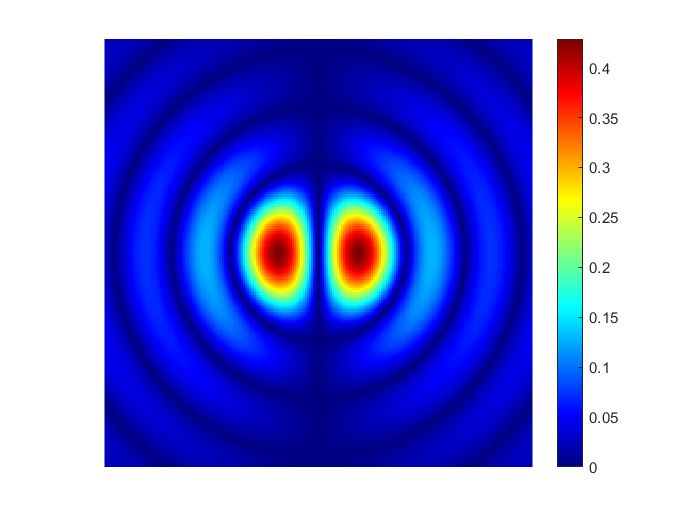

figure
imagesc(abs(Ez))
axis off 
axis square
colormap(jet)
colorbar

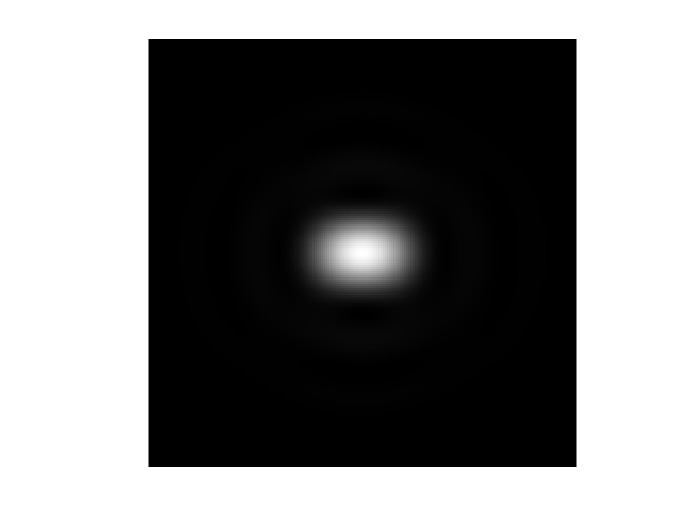

figure
imagesc(abs(Ex).^2+abs(Ey).^2+abs(Ez).^2)
axis off 
axis square
colormap(gray)

## 偶极子成像（均匀介质发射，对应原文5.2）

#### 原论文的表示方式

最终转到了笛卡尔坐标系，相当复杂了，一旦回到笛卡尔坐标系，就需要进行两次phi方向的坐标变换，因此会引入二阶贝塞尔函数相关的积分表达式，使得计算复杂度上升一倍，可谓绝顶麻烦

另外，原文的符号有问题，已经根据引文更正了

因为最终结果以归一化结果呈现，所以计算过程中忽略了部分常参数

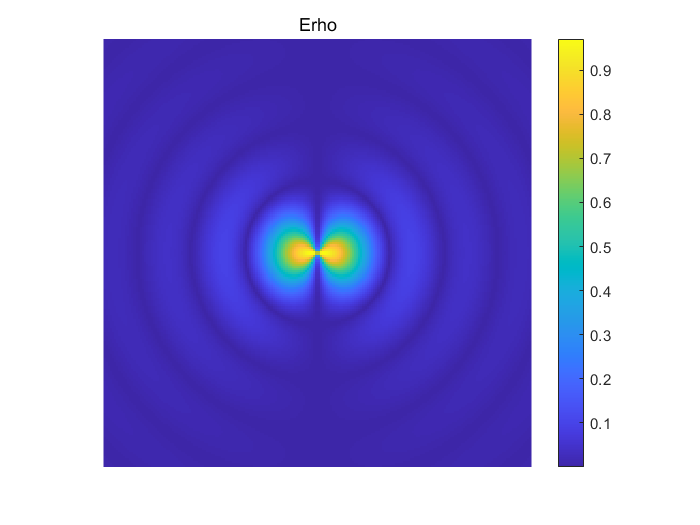

clear
% 偶极子取向
px = 1;
py = 0;
pz = 0;
lambda = 560*1e-9;  % 波长
n1 = 1; % 各层折射率
n2 = 1;
NA = 1;  % 数值孔径
mag = 60;   % 放大率
z = 0*1e-9; % 像方离焦情况
thetamax = asin(NA/n2/mag); % 成像透镜最大张角
k0 = 2*pi/lambda;   % 自由空间波矢    
k2 = 2*pi*n2/lambda;    % 像空间波矢
f = 0.2;    % 成像透镜焦距

theta1 = @(theta2) asin(n2*sin(theta2)/n1*mag); % 通过出射角度推算入射角度
A = @(theta2) -1i*f*k2/2/pi*sqrt(cos(theta2)./cos(theta1(theta2))).*sin(theta2)...
    .*exp(1i*k2*z*cos(theta2));   % A函数

x = -mag*lambda*linspace(-2,2,200);
y = x;
[x,y] = meshgrid(x,y);
[phi,rho] = cart2pol(x,y);

f0A = @(theta2) A(theta2)...
    .*(1+cos(theta1(theta2)).*cos(theta2))...
    .*besselj(0,k2*rho.*sin(theta2));
f0B = @(theta2) A(theta2)...
    .*sin(theta1(theta2)).*sin(theta2)...
    .*besselj(0,k2*rho.*sin(theta2));
f1A = @(theta2) A(theta2)...
    .*cos(theta2).*sin(theta1(theta2))...
    .*besselj(1,k2*rho.*sin(theta2));
f1B = @(theta2) A(theta2)...
    .*sin(theta2).*cos(theta1(theta2))...
    .*besselj(1,k2*rho.*sin(theta2));
f2A = @(theta2) A(theta2)...
    .*(1-cos(theta1(theta2)).*cos(theta2))...
    .*besselj(2,k2*rho.*sin(theta2));

K0A = integral(f0A,0,thetamax,'ArrayValued',1);
K0B = integral(f0B,0,thetamax,'ArrayValued',1);
K1A = integral(f1A,0,thetamax,'ArrayValued',1);
K1B = integral(f1B,0,thetamax,'ArrayValued',1);
K2A = integral(f2A,0,thetamax,'ArrayValued',1);

Exi = px/2*(K0A + K2A.*cos(2*phi)) - 1i*pz*K1A.*cos(phi) + py/2*K2A.*sin(2*phi);
Eyi = py/2*(K0A - K2A.*cos(2*phi)) - 1i*pz*K1A.*sin(phi) + px/2*K2A.*sin(2*phi);
Ezi = pz*K0B - 1i*K1B.*(px*cos(phi) + py*sin(phi));
P = max(abs(Exi),[],'all');
Exi = Exi/P;
Eyi = Eyi/P;
Ezi = Ezi/P;

Erho = Exi.*cos(phi) + Eyi.*sin(phi);
Ephi = -Exi.*sin(phi) + Eyi.*cos(phi);

figure
imagesc(abs(Erho))
axis off 
axis square
colorbar
title('Erho')

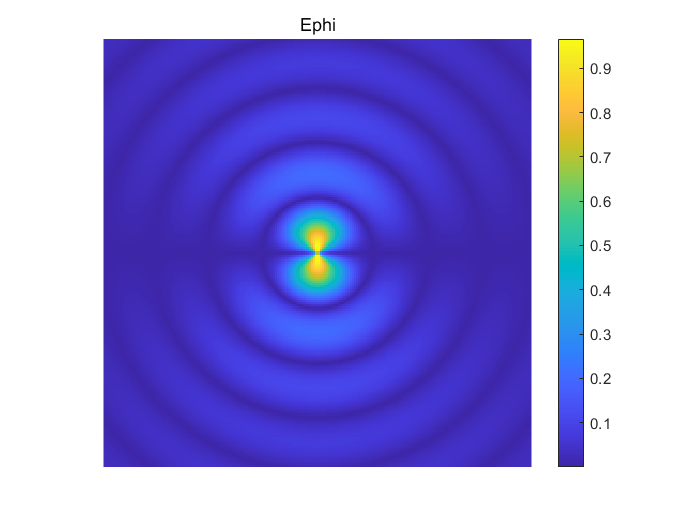

figure
imagesc(abs(Ephi))
axis off 
axis square
colorbar
title('Ephi')

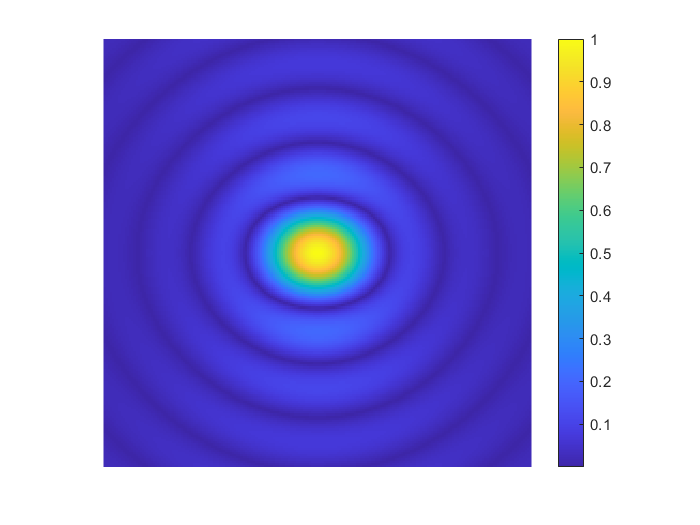


figure
imagesc(abs(Exi))
axis off 
axis square
colorbar

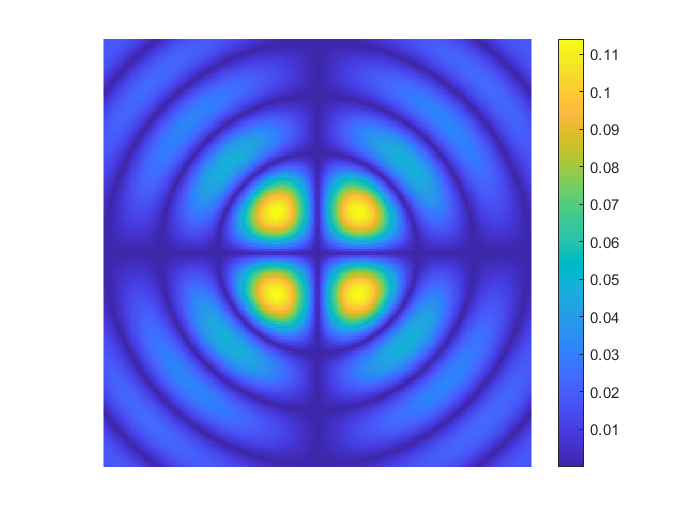

figure
imagesc(abs(Eyi))
axis off 
axis square
colorbar

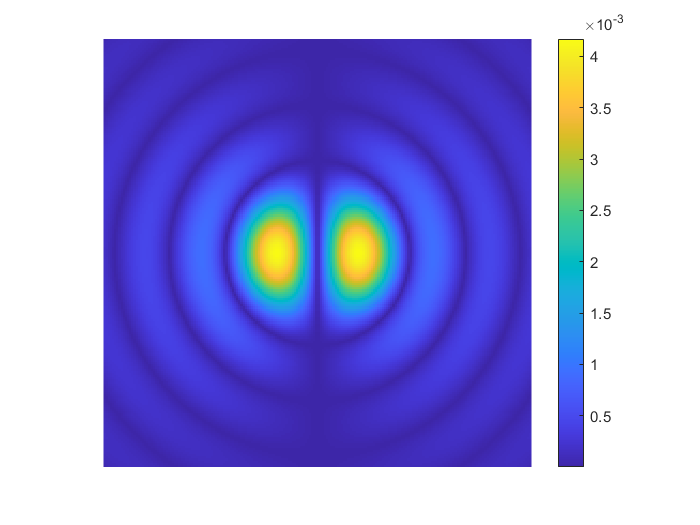

figure
imagesc(abs(Ezi))
axis off 
axis square
colorbar

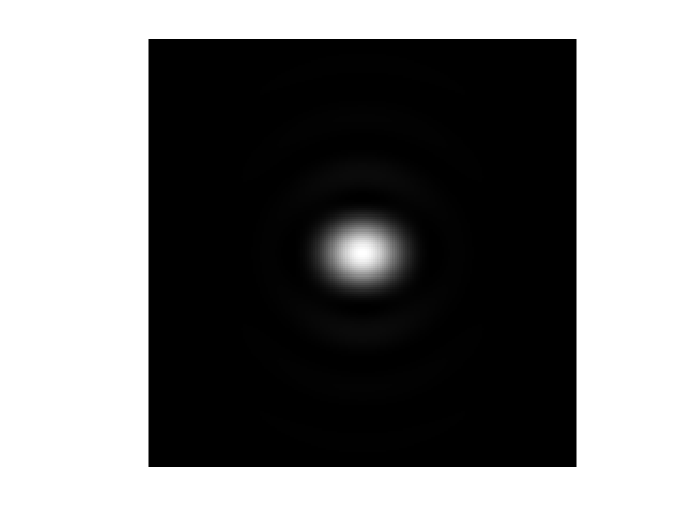

figure
imagesc(abs(Exi).^2+abs(Eyi).^2+abs(Ezi).^2)
axis off 
axis square
colormap(gray)